load('adjacent_metrics_agg_200801-184941_0.mat', 'res');

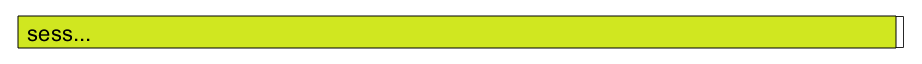

n_sess = numel(res);

[signal, noise, noise_shuf] = deal(cell(1,n_sess));

n_bin_bounds = 38;

progressbar('sess...');
for sess_i = 1:n_sess
    R = res(sess_i).results_table;
    [n_reps, n_n] = size(R);
    [signal{sess_i}, noise{sess_i}, noise_shuf{sess_i}] = deal(zeros(n_reps, n_n, n_bin_bounds));
    for rep_i = 1:n_reps
        for n_i = 1:n_n
            T = R{rep_i, n_i};
            signal{sess_i}(rep_i, n_i, :) = T{'m', 'se'};
            noise{sess_i}(rep_i, n_i, :) = T{'m', 'ce'};
            noise_shuf{sess_i}(rep_i, n_i, :) = T{'m', 'ue'};
        end
    end
    progressbar(sess_i/n_sess);
end

ix = 69;

s = signal{ix};
s_m = squeeze(mean(s)); s_s = squeeze(std(s)./sqrt(size(s,1)));

n = noise{ix};
n_m = squeeze(mean(n)); n_s = squeeze(std(n)./sqrt(size(n,1)));

ns = noise_shuf{ix};
ns_m = squeeze(mean(ns)); ns_s = squeeze(std(ns)./sqrt(size(ns,1)));


snr = s ./ n;
snr_m = squeeze(mean(snr)); snr_s = squeeze(std(snr)./sqrt(size(snr,1)));

snrs = s ./ ns;
snrs_m = squeeze(mean(snrs)); snrs_s = squeeze(std(snrs)./sqrt(size(snrs,1)));

nneu = res(ix).n_sizes;

%bb2kd = @(bb) sprintf('Bin %d, isleft? %d', ceil(bb/2), mod(bb,2));
bb2kd = @(bb) [ceil(bb/2), mod(bb,2)];

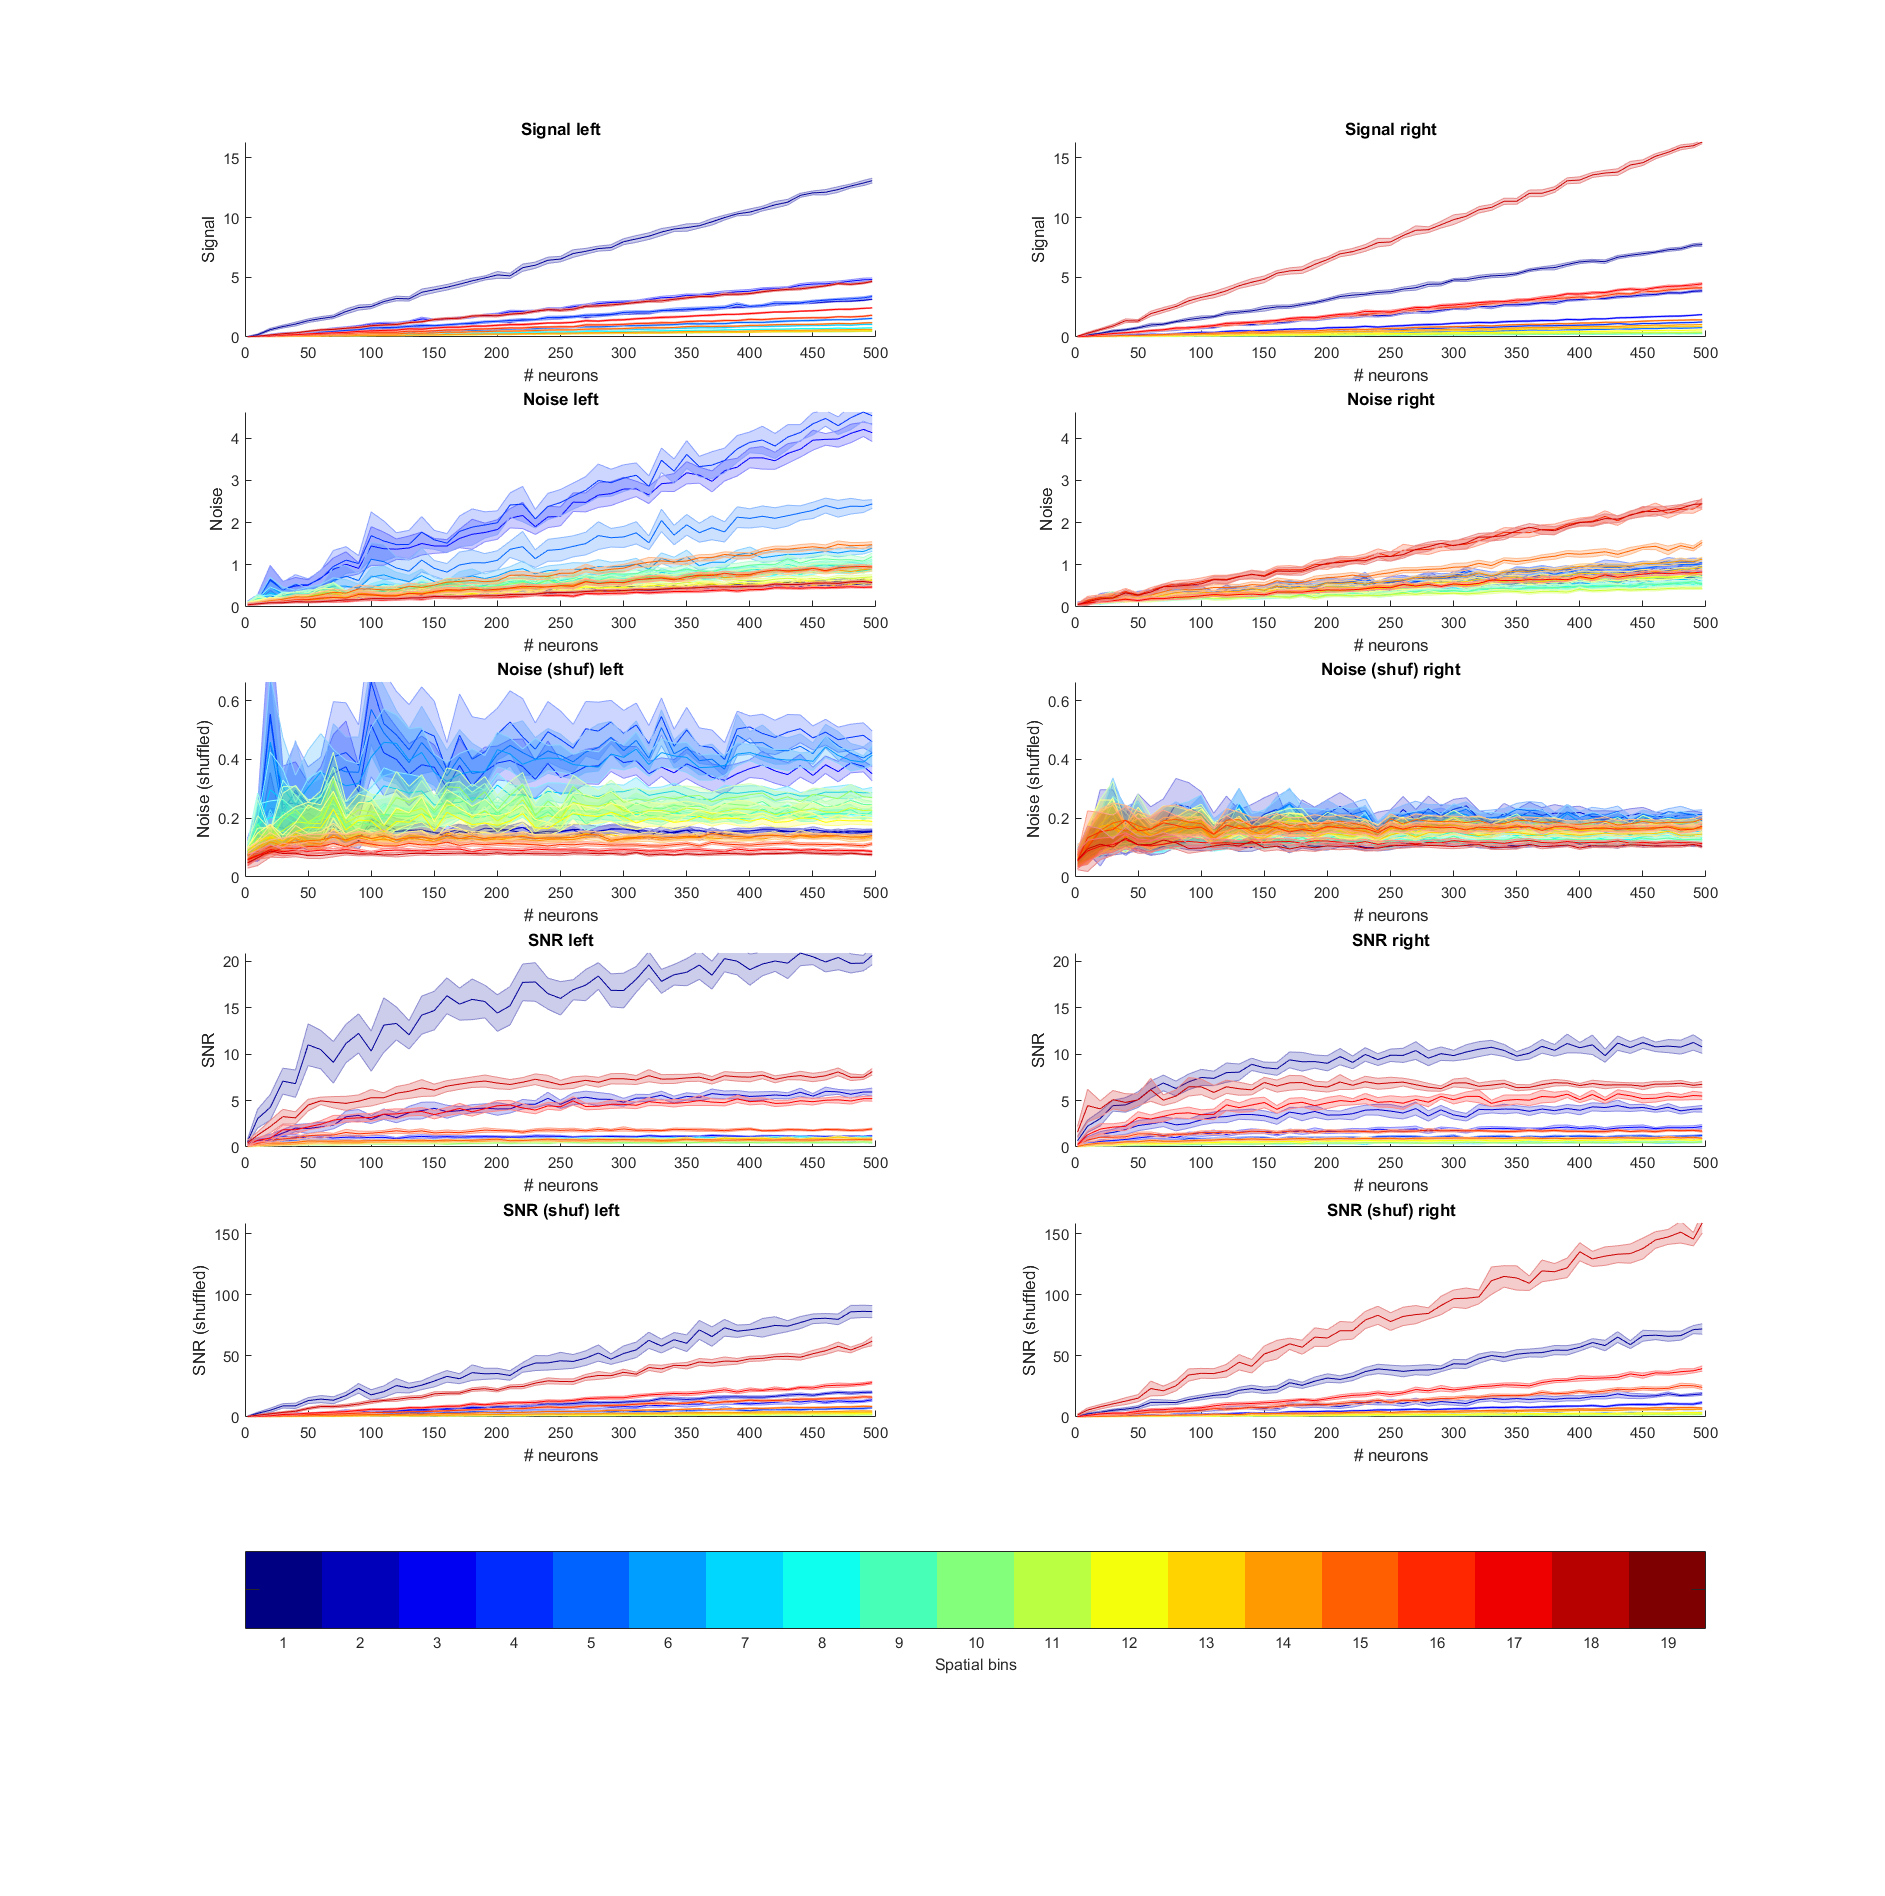

figure('Units',"inches", 'Position',[3.5603    0.8276   16.2500   16.3448]);

bin_colors = jet(n_bin_bounds/2);

for b = 1:n_bin_bounds
    kd = bb2kd(b);
    k = kd(1);
    switch kd(2)
        case 0
            d = 'right';
            is_right = 1;
        case 1
            d = 'left';
            is_right = 0;
    end
    
    
    subplot(6,2,1*2 + is_right - 1);
    shadedErrorBar(nneu.', s_m(:,b), s_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'Signal'
    ylim([0 max(s_m(:))]);
    %set(gca, 'YScale', 'log');
    
    subplot(6,2,2*2 + is_right - 1);
    shadedErrorBar(nneu.', n_m(:,b), n_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'Noise'
    ylim([0 max(n_m(:))]);
    %set(gca, 'YScale', 'log');
    
    subplot(6,2,3*2 + is_right - 1);
    shadedErrorBar(nneu.', ns_m(:,b), ns_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'Noise (shuffled)'
    ylim([0 max(ns_m(:))]);
    %set(gca, 'YScale', 'log');
    
    subplot(6,2,4*2 + is_right - 1);
    shadedErrorBar(nneu.', snr_m(:,b), snr_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'SNR'
    ylim([0 max(snr_m(:))]);
    %set(gca, 'YScale', 'log');
    
    subplot(6,2,5*2 + is_right - 1);
    shadedErrorBar(nneu.', snrs_m(:,b), snrs_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'SNR (shuffled)'
    ylim([0 max(snrs_m(:))]);
    %set(gca, 'YScale', 'log');
end
subplot(6,2,1); title 'Signal left'
subplot(6,2,2); title 'Signal right'

subplot(6,2,3); title 'Noise left'
subplot(6,2,4); title 'Noise right'

subplot(6,2,5); title 'Noise (shuf) left'
subplot(6,2,6); title 'Noise (shuf) right'

subplot(6,2,7); title 'SNR left'
subplot(6,2,8); title 'SNR right'

subplot(6,2,9); title 'SNR (shuf) left'
subplot(6,2,10); title 'SNR (shuf) right'
subplot(6,2,[11 12]);
imagesc(1:19);
axis image
colormap jet
set(gca, 'YTickLabels', []);
xticks(1:19);
set(get(gca, 'XAxis'), 'TickLength', [0 0]);
xlabel 'Spatial bins'

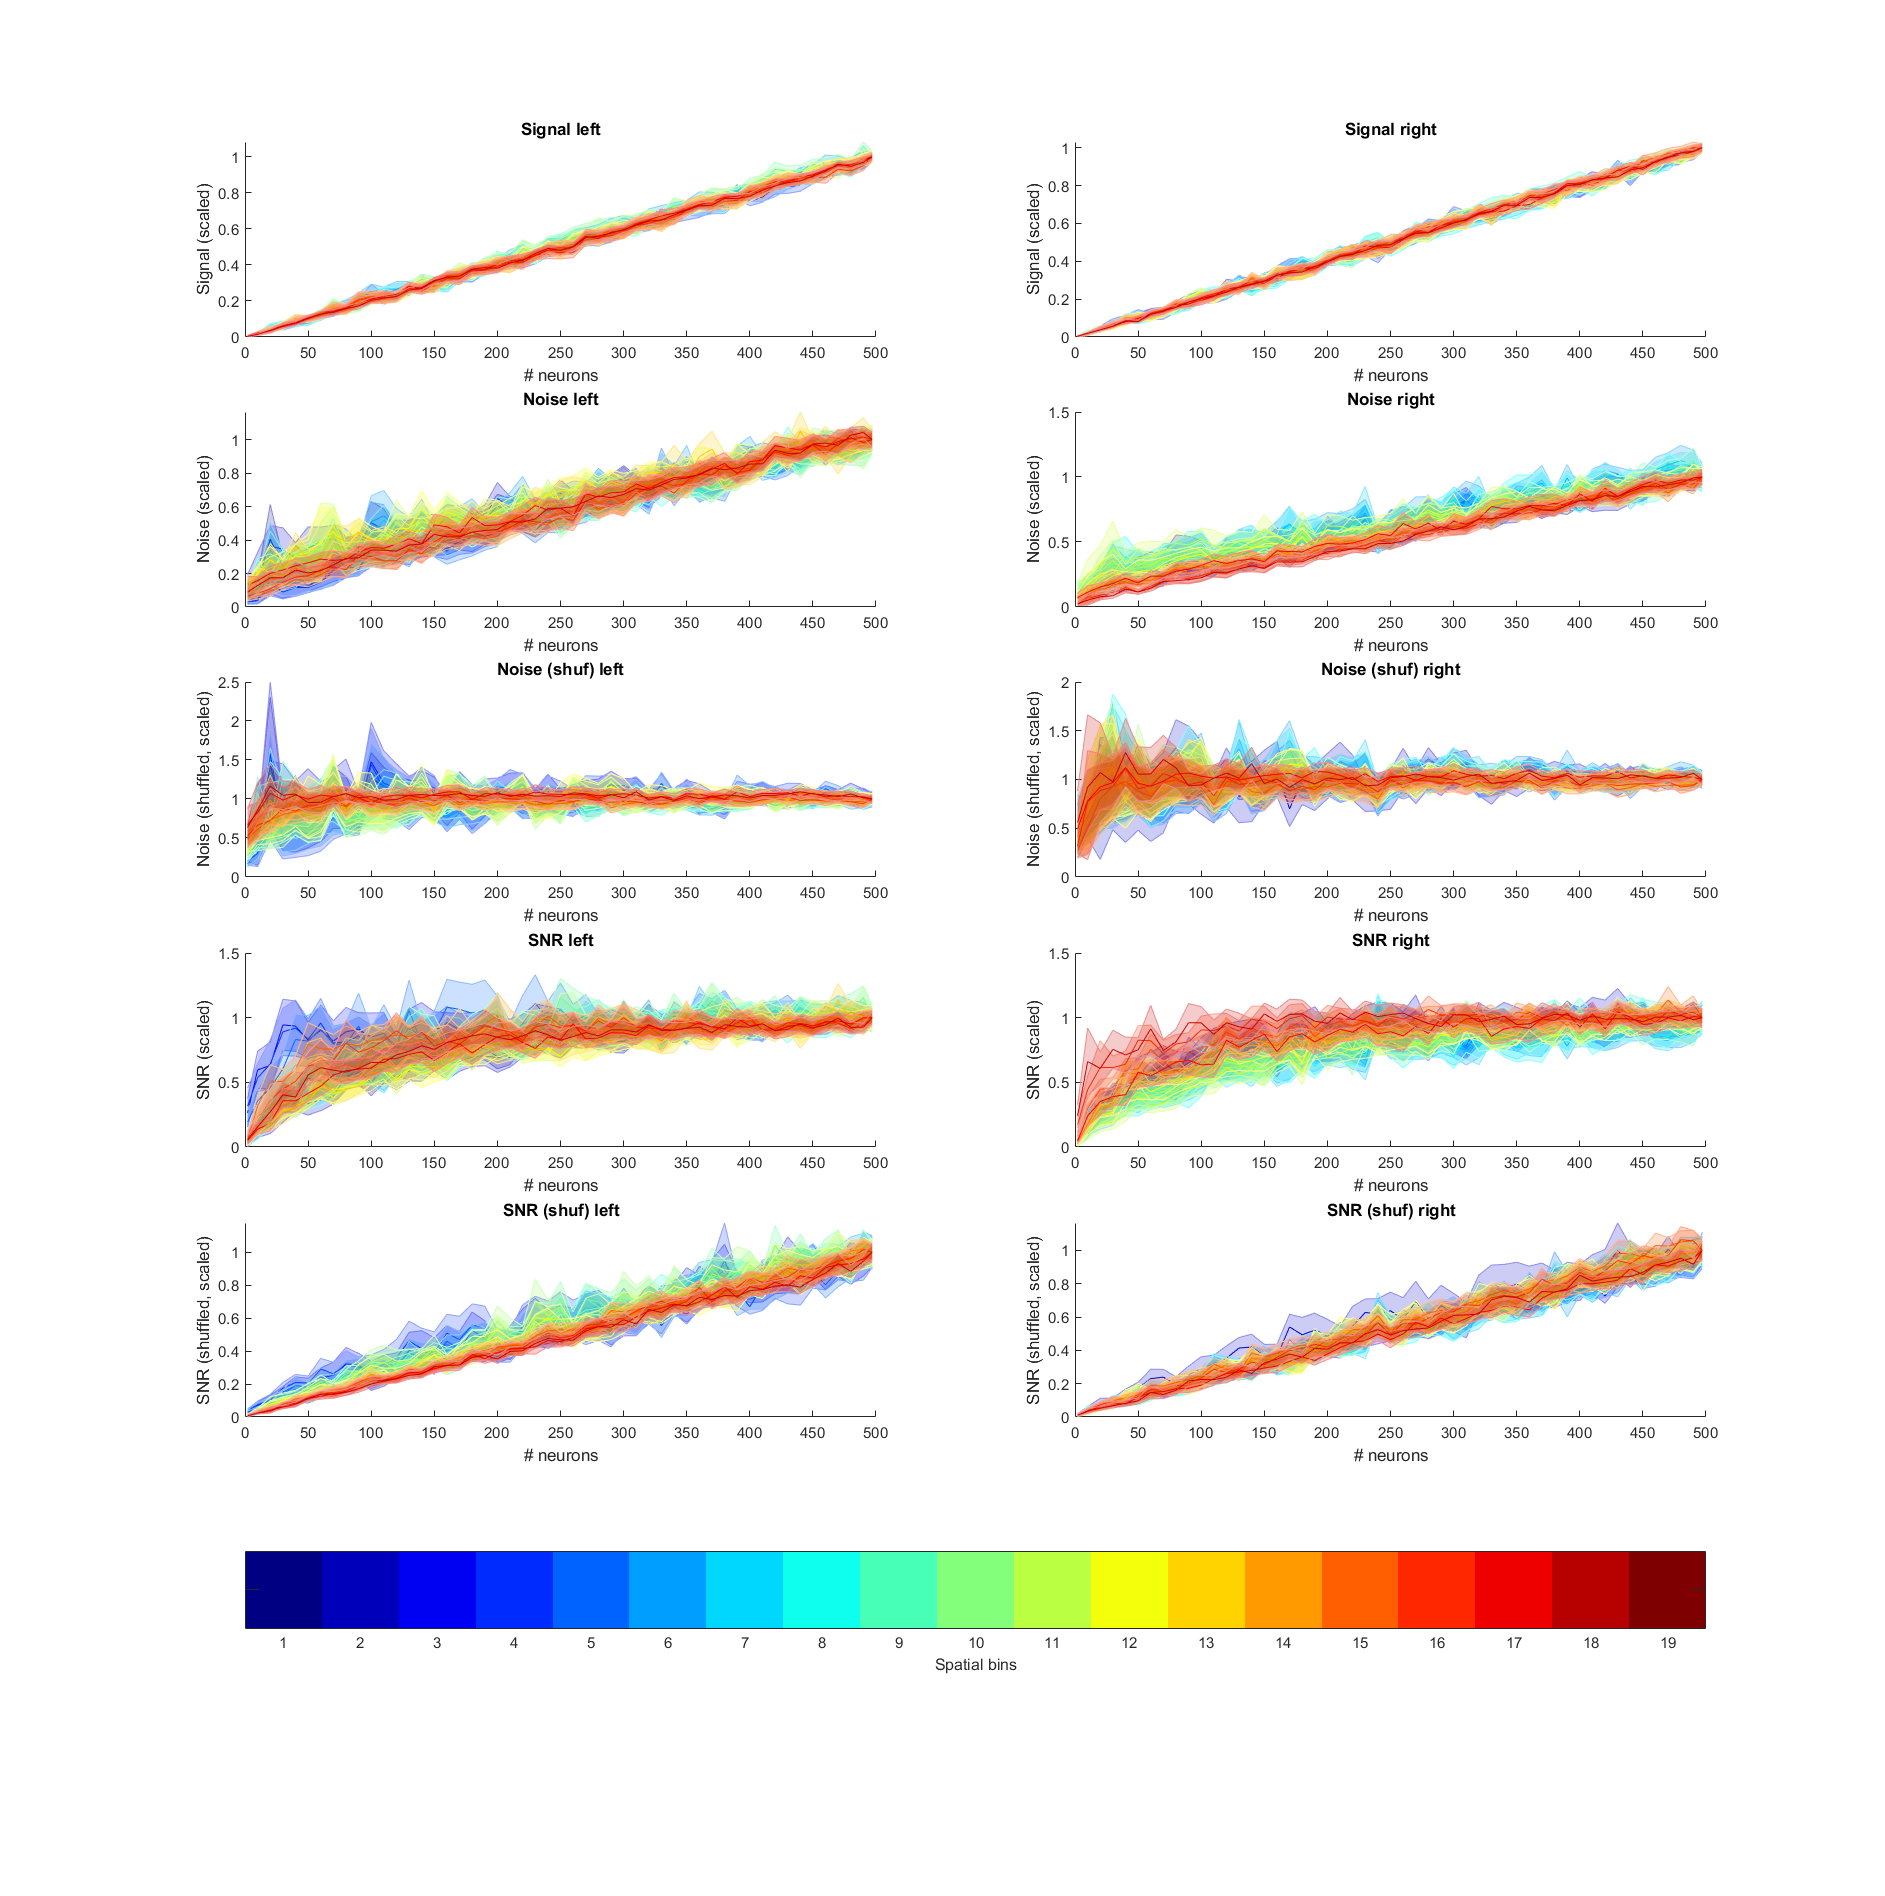

figure('Units',"inches", 'Position',[3.5603    0.8276   16.2500   16.3448]);

bin_colors = jet(n_bin_bounds/2);

for b = 1:n_bin_bounds
    kd = bb2kd(b);
    k = kd(1);
    switch kd(2)
        case 0
            d = 'right';
            is_right = 1;
        case 1
            d = 'left';
            is_right = 0;
    end
    
    
    subplot(6,2,1*2 + is_right - 1);
    scale = s_m(end,b);
    shadedErrorBar(nneu.', s_m(:,b)./scale, s_s(:,b).*1.96./scale, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'Signal (scaled)'
    %ylim([0 max(s_m(:))]);
    
    
    subplot(6,2,2*2 + is_right - 1);
    scale = n_m(end,b);
    shadedErrorBar(nneu.', n_m(:,b)./scale, n_s(:,b).*1.96./scale, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'Noise (scaled)'
    %ylim([0 max(n_m(:))]);
    
    
    subplot(6,2,3*2 + is_right - 1);
    scale = ns_m(end,b);
    shadedErrorBar(nneu.', ns_m(:,b)./scale, ns_s(:,b).*1.96./scale, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'Noise (shuffled, scaled)'
    %ylim([0 max(ns_m(:))]);
    
    
    subplot(6,2,4*2 + is_right - 1);
    scale = snr_m(end,b);
    shadedErrorBar(nneu.', snr_m(:,b)./scale, snr_s(:,b).*1.96./scale, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'SNR (scaled)'
    %ylim([0 max(snr_m(:))]);
    
    
    subplot(6,2,5*2 + is_right - 1);
    scale = snrs_m(end,b);
    shadedErrorBar(nneu.', snrs_m(:,b)./scale, snrs_s(:,b).*1.96./scale, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'SNR (shuffled, scaled)'
    %ylim([0 max(snrs_m(:))]);
    
end
subplot(6,2,1); title 'Signal left'
subplot(6,2,2); title 'Signal right'

subplot(6,2,3); title 'Noise left'
subplot(6,2,4); title 'Noise right'

subplot(6,2,5); title 'Noise (shuf) left'
subplot(6,2,6); title 'Noise (shuf) right'

subplot(6,2,7); title 'SNR left'
subplot(6,2,8); title 'SNR right'

subplot(6,2,9); title 'SNR (shuf) left'
subplot(6,2,10); title 'SNR (shuf) right'
subplot(6,2,[11 12]);
imagesc(1:19);
axis image
colormap jet
set(gca, 'YTickLabels', []);
xticks(1:19);
set(get(gca, 'XAxis'), 'TickLength', [0 0]);
xlabel 'Spatial bins'